## GPU Stress-Energy Tensor Computation

Requires MATLAB's GPU Toolbox

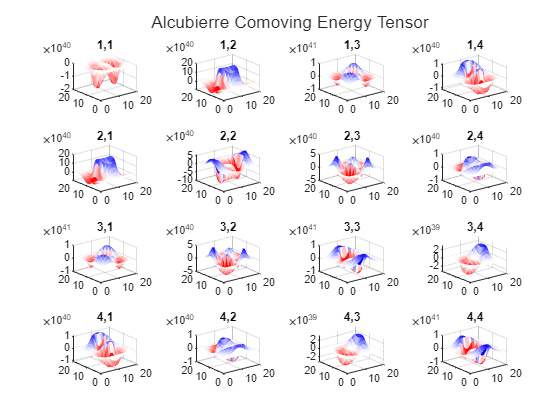

%% Alcubierre
gridSize = [1 20 20 20];
worldCenter = (gridSize+1)./2;
velocity = 0.5;
R = 5;
sigma = 0.5;
Metric = metricGet_AlcubierreComoving(gridSize,worldCenter,velocity,R,sigma);

% Compute energy tensor on GPU
EnergyTensorGPU = getEnergyTensor(Metric,1); % Note the 1 as a second input arg

% Plotting Energy Tensor
clf
for i = 1:4
    for j = 1:4
        h = nexttile;
        surfq(EnergyTensorGPU.tensor{i,j}(1,:,:,round(worldCenter(4))),'EdgeColor','none')
        title(num2str(i) + "," + num2str(j))
    end
end
sgtitle(Metric.name + " Energy Tensor")

## When to use the GPU?

### 20x20x20 Grid

%% Alcubierre For 20*20*20
gridSize = [1 20 20 20];
worldCenter = (gridSize+1)./2;
velocity = 0.5;
R = 5;
sigma = 0.5;
Metric = metricGet_AlcubierreComoving(gridSize,worldCenter,velocity,R,sigma);

% Compute energy tensor on GPU
tic
EnergyTensorGPU = getEnergyTensor(Metric,1);
toc

Elapsed time is 0.717947 seconds.



% Compute energy tensor on CPU
tic
EnergyTensor = getEnergyTensor(Metric,0);
toc

Elapsed time is 0.095965 seconds.


CPU takes a shorter time for smaller grids.

### 60x60x60 Grid

%% Alcubierre For 60*60*60
gridSize = [1 60 60 60];
worldCenter = (gridSize+1)./2;
velocity = 0.5;
R = 5;
sigma = 0.5;
Metric = metricGet_AlcubierreComoving(gridSize,worldCenter,velocity,R,sigma);

% Compute energy tensor on GPU
tic
EnergyTensorGPU = getEnergyTensor(Metric,1);
toc

Elapsed time is 0.760711 seconds.



% Compute energy tensor on CPU
tic
EnergyTensor = getEnergyTensor(Metric,0);
toc

Elapsed time is 1.087282 seconds.


GPU takes a shorter time for larger grids.

There is an upper limit to the gridSize of metrics that you can compute using the GPU. This will depend on how much memory your GPU has.

Whether you should run an evaluation on the CPU vs. the GPU will depend on your specific CPU and GPU. Below grid sizes of about 30 to 50 cubic units, the CPU should be used for maximum speed. Above this range, faster computation will be done by the GPU up to the GPU memory limit for your specific GPU. Above this GPU limit, CPU computation will need to be done up to your machine's CPU memory limit. (Note: these large CPU computations will take a very long time).